# EE4311 [2610] Lab 1: PD Controller

## 1    Introduction

In this course, we will use an inverted pendulum problem to introduce fuzzy logic and meta-heuristic algorithms. In lab 1, we will try to understand the control problem by implementing a simple PD controller.

Let $\gamma$ is the angle an inverted pendulum makes with the ground's perpendicular. The controller aims to keep $\gamma=0$ from an initial angle $\gamma_0$ where $\gamma_0 \in\{-10^\circ, -5^\circ, 5^\circ, 10^\circ\}$. The pendulum is mounted on a moving cart which is moving along an angled slope. The cart is controlled by applying a force $F$.

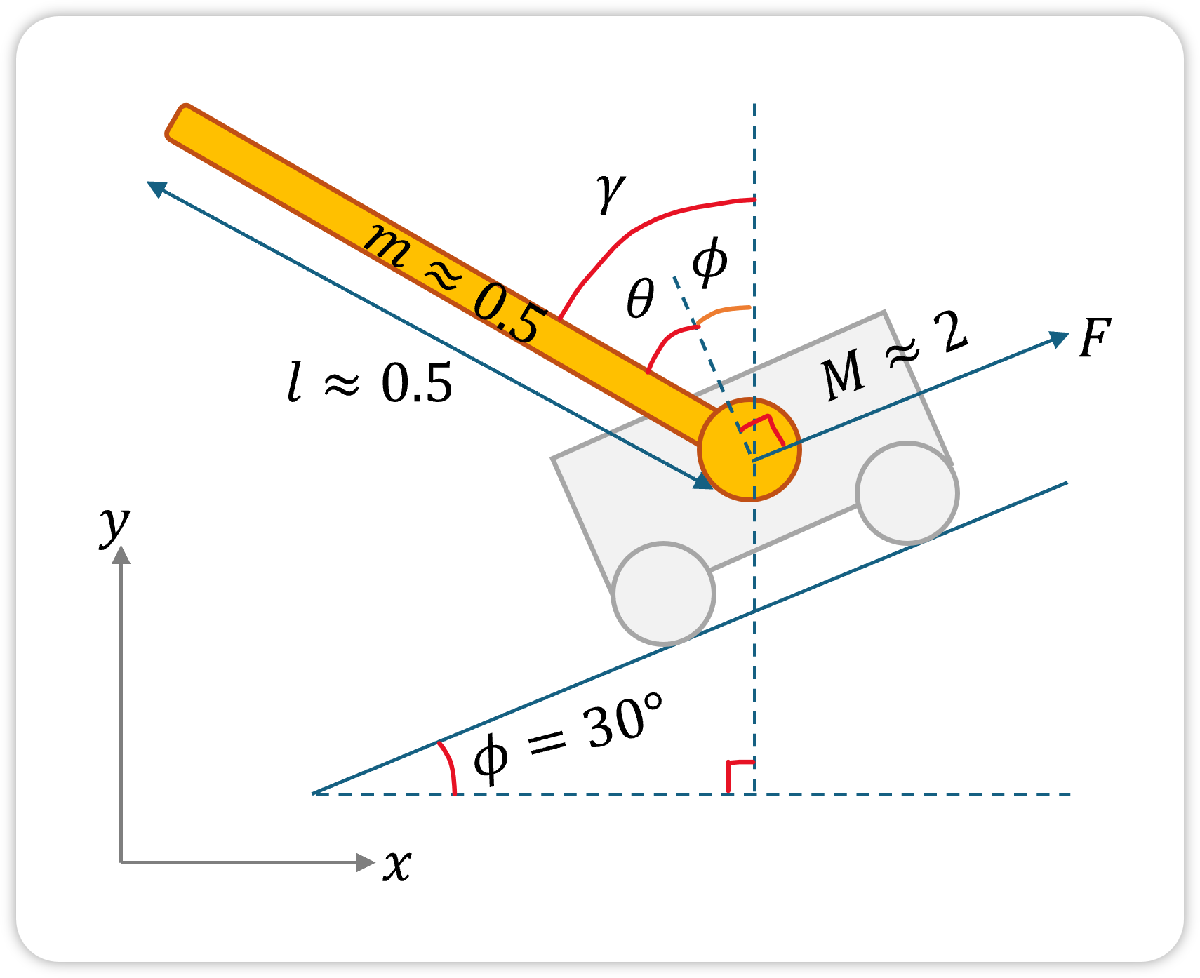

Angles are positive in the anticlockwise direction. In the image above, $\gamma>0$. A positive force $F$ moves the cart to the right of the image and up the slope. The slope angle $\phi=30\degree$ and the pendulum mass $m\approx0.5$ kg, cart body mass $M\approx2$ kg, and pendulum length $l\approx0.5$ m are randomized based on your matric number.

The worksheet is organized as follows:

- Section 2 requires you to define the random seed and tune parameters.

- Section 3 requires you to define the PD controller to balance the pendulum.

- Section 4 simulates the system with the controller, and outputs the responses.

- Section 5 allows you to export and figures that are generated by the worksheet.

- Section 6 includes deadlines and submission requirements.

- Section 7 shows a preview of the questions to be answered on Canvas for this lab.

## 2    Definitions

In this section, we define parameters and construct the system.

### 2.1    Initializations of Constants

To prevent too many variables from showing up (polluting) in the workspace, we gather and define constant values in the `constants` struct.

- Insert the numeric digits of your matric number to seed the random number generator with `rng`. This allows reproducibility of results. If a member has matric number `A0123456A` then the line should look like `rng(123456)`.

clear all; close all; clc; format compact
rng(284748); % !TODO (1)
 
constants = struct();
constants.G = 9.8;
constants.M_CART = rand() * 1 + 1.5; % cart mass, kg
constants.M_PEND = rand() * 0.2 + 0.4; % pend mass, kg
constants.L_PEND = rand() * 0.2 + 0.4; % pend length, m
constants.PHI = 30; % slope angle, deg
constants.GAMMA_SET = 1; % settling angle, deg
constants.START_GAMMAS = [-10, -5, 5, 10]; % deg
constants.F_UNI = [-inf, inf];
constants.D_UNI = [-inf, inf];
constants.P_UNI = [-inf, inf];
constants.DESIRED_GAMMA = 0;
constants.DESIRED_GAMMA_VEL = 0;


fprintf("Slope=%.3f deg; Cart mass=%.3f kg; Pend mass=%.3f kg; Pend length=%.3f m\n", constants.PHI, constants.M_CART, constants.M_PEND, constants.L_PEND);

Slope=30.000 deg; Cart mass=1.574 kg; Pend mass=0.517 kg; Pend length=0.474 m


### 2.2    Find Weight Along Slope

Find the magnitude of the force pointing down the slope that is contributed by the weight of the system. This force is parallel to and pointing down the slope, and may be useful for tuning. Let this be stored in the `constants.WEIGHT`. To calculate the force, the following constants may be used:

- `constants.G`: Acceleration due to gravity, in m/s/s.

- `constants.PHI`: the slope angle, in ***degrees***.

- `constants.M_CART`: the mass of the cart, in kg

- `constants.M_PEND`: the mass of the pendulum, in kg.

constants.WEIGHT = (constants.M_CART + constants.M_PEND)*(constants.G)*(sind(constants.PHI)); % !TODO
fprintf("Cart Weight=%.3f kg  \n", constants.WEIGHT);

Cart Weight=10.244 kg  


### 2.3    Specify Proportional and Derivative Gains

Specify the proportional and derivative gains here. **Come back here later, after simulating the responses, to tune the gains.**

- Tune the proportional gain `kp`.

- Tune the derivative gain `kd`.

kp = 2.75; % !TODO (1)
kd =0.4 ; % !TODO (2)

## 3    Controller

The angle $\gamma$ (deg) and its velocity $\dot{\gamma}$ (deg/s) are stored in `gamma` and `gamma_vel` respectively. In the function `controller()`, implement the PD controller to output a force `f` to move the cart. 

- Calculate the proportional error `p`. It is the desired angle subtracted by the current angle `gamma`.

- Calculate the proportional control `f_p`, which is the proportional gain `kp` multiplied by the proportional error.

- Calculate the derivative error `d`. It is the desired angular velocity subtracted by the current angular velocity `gamma_vel`.

- Calculate the derivative control `f_d`, which is the derivative gain `kd` multiplied by the derivative error.

- Calculate the output force `f`, which is the sum of the proportional and derivative controls.

Run this code block after the controller is modified, so that the changes are registered by the program.

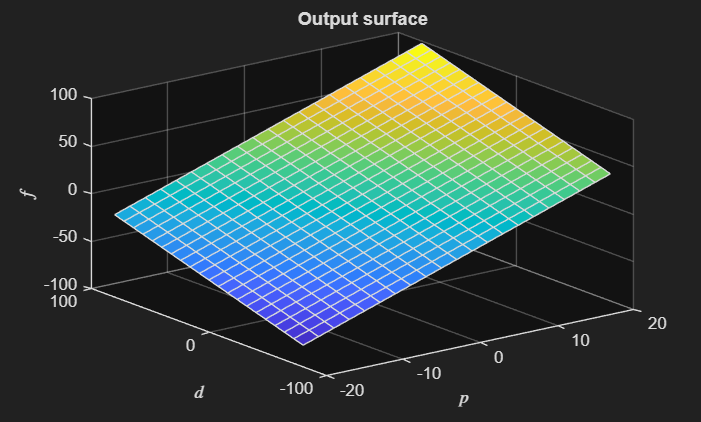



function [f, p, d] = controller(kp, kd, gamma, gamma_vel, constants)
   p = constants.DESIRED_GAMMA - gamma; % !TODO (1) 

   f_p = kp*p; % !TODO (2)
   d = constants.DESIRED_GAMMA_VEL - gamma_vel; % !TODO (3)
   f_d = kd*d; % !TODO (4)
   f = f_p + f_d + constants.WEIGHT; % !TODO (5)

end

### 3.1    Plot Output Surface

The following function visualizes the output force based on the proportional control and derivative control, and may be useful for the project. 

function fig1 = plotOutputSurface(kp, kd, constants)
    % plots the output force with respect to the input gamma and gamma_vel
    
    [gammas, gamma_vels] = meshgrid(-20:2:20, -80:8:80);
    F = zeros(size(gammas));
    P = zeros(size(gammas));
    D = zeros(size(gammas));

    for i = 1:size(gammas, 1)
        for j = 1:size(gammas, 2)
            [F(i,j), P(i,j), D(i,j)] = controller(kp, kd, gammas(i,j), gamma_vels(i,j), constants);
        end
    end

    fig1 = figure(1);
    surf(P, D, F);
    title('Output surface')
    xlabel('$p$', 'Interpreter', 'latex')
    ylabel('$d$', 'Interpreter', 'latex')
    zlabel('$f$', 'Interpreter', 'latex')
end

fig1 = plotOutputSurface(kp, kd, constants);
set(fig1, 'Visible', 'on');

## 4    Simulation

Ensure that the all code from the previous section are correct. Run the simulation below, and **tune **`kp`** and **`kd`** above** to ensure that the following requirements are met.

- The settling time for 1 degree must be 0.5s or less for all starting angles $\gamma_0 \in\{-10^\circ, -5^\circ, 5^\circ, 10^\circ\}$. The settling time can be seen in the figure as $t_s$.

- Overshoot in $\gamma$ is less than $1\degree$.

- Steady state $\gamma$ should be as close to zero as possible. Hint: you may need to add something in the `controller` function.

- Negligible oscillations in all responses.

- Ignore the cart's displacement and velocity.

The following tuning process is suggested:

- Set the slope angle to 0 in the first code block (`constants.PHI = 0`, at the first code block). This is to balance the force on the pendulum and make it easier to tune.

- Start from `kp = 1`, `kd = 0`. Increment kp until the response in gamma steadily oscillates around the setpoint $\gamma = 0$.

- Keeping the previous kp, now set `kd = 1`, and `i`ncrement kd until the response in gamma begins to converge at the setpoint.

- Observe what happens to the overshoot when `kd` is adjusted.

- Observe what happens to the settling time $t_s$ and any overshoot when `kp` is increased.

- Based on your observations, re-tune kp or kd depending on the observations if the requirements above *cannot* be met.

- Now, **put the slope angle back to **$30\degree$ (`constants.PHI = 30`). In this case, gamma is unable to converge to zero degrees because the controller's output force is zero, causing the cart to begin rolling down the slope and the pendulum to swing in the opposite direction. Modify the controller's output force to balance the cart.

**Just run. Ignore the code in this section.** The code uses Euler Lagrange formulation to simulate the system. 

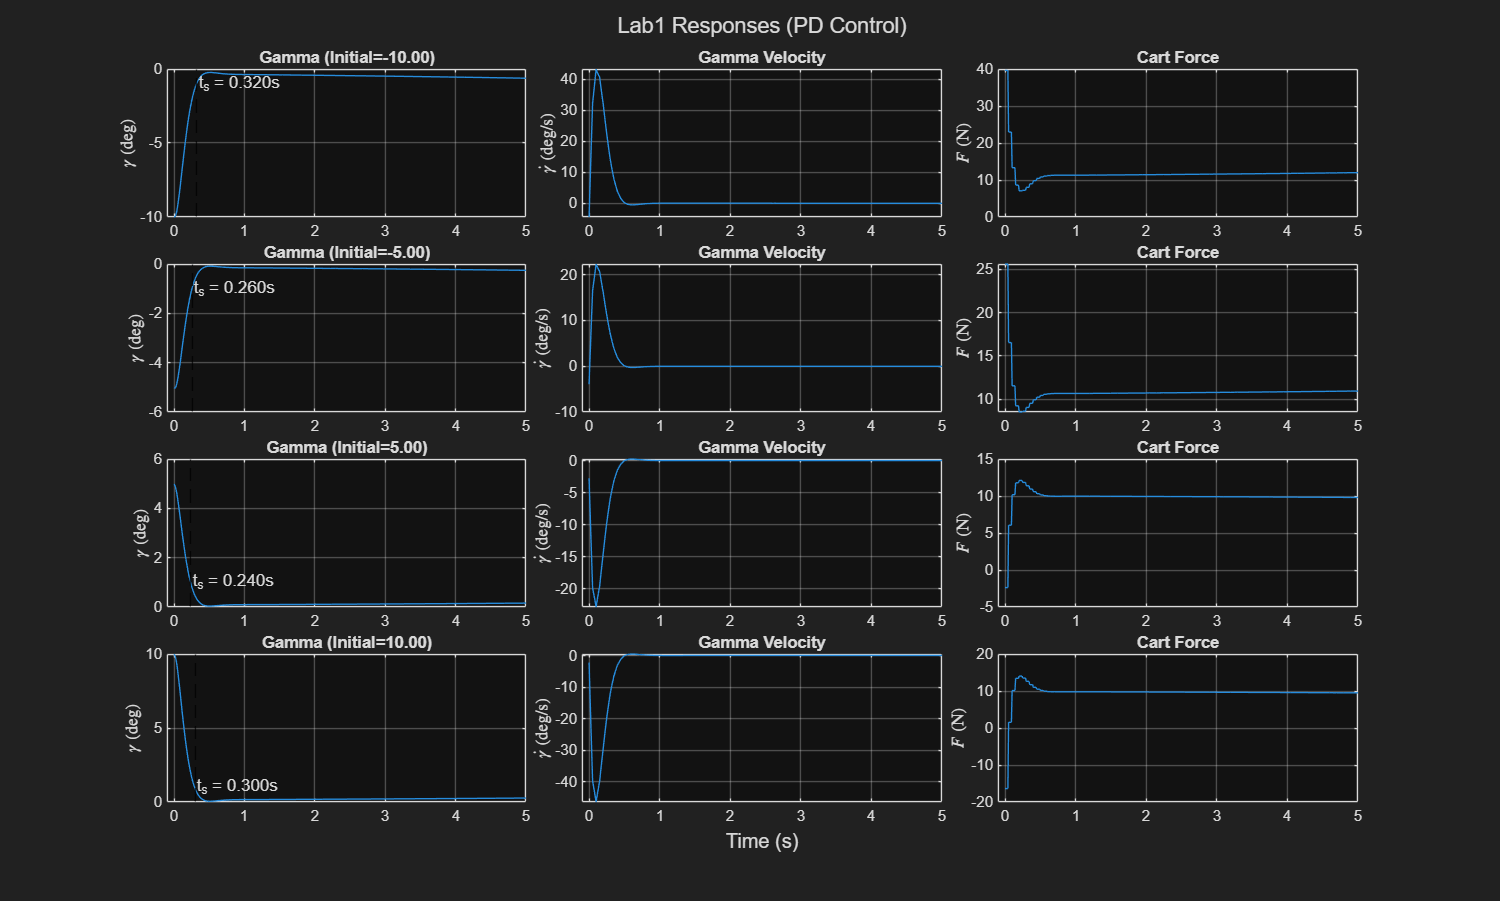

function response = simulate(kp, kd, constants, start_gamma)
% start_gamma is in degrees.

DT = 0.01; % simulate frequency in seconds.
DT2 = DT * DT;
T_TOTAL = 5; % in seconds
CTRL_STEP = 5; % 5*DT is controller frequency.
KF_CART = 3; % cart friction coeff
KF_PEND = 1e-4; % pend friction coeff
S_PHI = sind(constants.PHI);

Saving images to C:\Users\adity\OneDrive\Documents\MATLAB


C_PHI = cosd(constants.PHI);

M_TOTAL = constants.M_CART + constants.M_PEND;

L76 = -constants.L_PEND * 7.0 / 6.0;
MML76 = M_TOTAL * L76;
WEIGHT = constants.G * S_PHI * M_TOTAL;

T = 0:DT:T_TOTAL; %sim for 0.01s for 10s
PS = nan(size(T)); % gamma
PV = nan(size(T));
F = nan(size(T));
f = 0;
theta = deg2rad(start_gamma - constants.PHI);
pv = 0;
cs = 0;
cv = 0;
for i = 1:numel(T)
    C_THETA = cos(theta);
    S_THETA = sin(theta);
    % From euler lagrange formulation
    tmp_a = f - 0.5*pv*pv*S_THETA - WEIGHT - cv*KF_CART;
    tmp_b = -constants.G * (S_THETA*C_PHI + C_THETA*S_PHI) - pv*KF_PEND;
    tmp_denom = MML76 - 0.5*C_THETA*C_THETA;
    ca = (L76*tmp_a + 0.5*C_THETA*tmp_b) / tmp_denom;
    pa = (-C_THETA*tmp_a + M_TOTAL*tmp_b) / tmp_denom;
    % linear approximation
    theta = theta + pv*DT + 0.5*pa*DT2;
    ps = theta + deg2rad(constants.PHI);
    pv = pv + pa*DT;
    cs = cs + cv*DT + 0.5*ca*DT2;
    cv = cv + ca*DT;
    % controller
    if mod(i-1, CTRL_STEP) == 0
        % ps = ps + randn()*1e-4; % corrupt with noise
        % pv = pv + randn()*1e-4; % corrupt with noise
        % controller
        [f, ~, ~] = controller(kp, kd, rad2deg(wrapToPi(ps)), rad2deg(pv), constants);
        % saturate force like real world system
        f = clip(f, -50, 50);
    end
    PS(i) = ps;
    PV(i) = pv;
    F(i) = f;
end

response.gamma = rad2deg(wrapToPi(PS));
response.gamma_vel = rad2deg(PV);
response.force = F;
response.time = T;
end

% ================= function to analyze / evaluate response
function  response = evalResponse(response, constants)
idx = find(flip(response.gamma < -constants.GAMMA_SET | response.gamma > constants.GAMMA_SET), 1, "first"); % flip the ps, find the first index when the response is outside of settling gamma. 
if ~isempty(idx) && idx > 1 % has settling time. 
    response.settling_time = response.time(numel(response.gamma) - idx + 2);
else
    response.settling_time = inf;
end
end

% ================= run the simulation for all START_GAMMAS
responses = [];
for i = 1:numel(constants.START_GAMMAS)
    r = simulate(kp, kd, constants, constants.START_GAMMAS(i));
    r = evalResponse(r, constants);
    responses = [responses, r];
end

% ===================== plot
function  fig2 = plotResponses(responses, constants)
fig2 = figure(2);
fig2.Position = [0, 0, 1200, 720];
tld = tiledlayout(numel(constants.START_GAMMAS), 3, TileSpacing="tight");
title(tld, "Lab1 Responses (PD Control)");
xlabel(tld, "Time (s)");
for i = 1:numel(constants.START_GAMMAS)
    r = responses(i);

    nexttile
    plot(r.time, r.gamma)
    start_gamma = constants.START_GAMMAS(i);
    title(sprintf('Gamma (Initial=%.2f)', start_gamma));
    if (~isnan(r.settling_time))
        xline(r.settling_time, '--k');
        text(r.settling_time, sign(start_gamma) * constants.GAMMA_SET, sprintf('t_s = %.3fs', r.settling_time))
    end
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$\gamma$ (deg)", Interpreter="latex");

    nexttile
    plot(r.time, r.gamma_vel)
    title('Gamma Velocity');
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$\dot{\gamma}$ (deg/s)", Interpreter="latex");

    nexttile
    plot(r.time, r.force)
    title('Cart Force');
    grid on
    xlim([-0.1, r.time(end)])
    ylabel("$F$ (N)", Interpreter="latex");
end
end

fig2 = plotResponses(responses, constants);
set(fig2, 'Visible', 'on');

## 5    Export Figures

You can save the figures into images (`.png`) by running the code below. The images will be saved in the current folder.

% exportgraphics(fig1,'l1_parameters.pdf','BackgroundColor','none','ContentType','vector');
% exportgraphics(fig2,'l1_responses.pdf','BackgroundColor','none','ContentType','vector');

fprintf("Saving images to %s\n", pwd());
exportgraphics(fig1,'l1_parameters.png','BackgroundColor','white');
exportgraphics(fig2,'l1_responses.png','BackgroundColor','white');

## 6    Administrative Requirements

- **Individual Work**, 100 marks in total, 10% of total grade.

- **Deadline W5 Sun (13 Sep) 23:59h**. See Canvas for most recent deadline.

### 6.1    Submit MLX Worksheet

- **Submit .mlx Worksheet** to `Canvas` ▶ `Assignments` ▶ `L1`:

- (5 marks) Rename the file as `l1_a########.mlx` in ***lowercase***, where `a#########` is your matric number (e.g. `l1_a0123456a.mlx`).

- (5 marks) **Your name should not appear** in the worksheet, only the matric number.

- (5 marks) Overshoot in gamma is less than $1\degree$ on the $30\degree$ slope.

- (5 marks) Settling time is less than 0.5s for all responses on the $30\degree$ slope.

- (5 marks) Zero steady state error for all responses on the $30\degree$ slope.

- (25 marks) will be based on your code.

- **No errors while running** to ensure that marks can be given. Some code will be copied to a solution template for testing, so change only the code as requested and do not modify the rest.

### 6.2    Answer Questions on Canvas

- **Answer written questions** in the next section on `Canvas` ▶ `Assignments` ▶ `L1Q`.

## 7    Questions

Answer the questions on L1Q on Canvas. Included here for convenience.

### 7.1    Effect of Proportional Gain on Response of Gamma

(20 marks) What effect does increasing the proportional gain have on reaching the setpoint $\gamma = 0$? Explain why.

### 7.2    Effect of Proportional Gain on Settling Time

(5 marks) State the effect of increasing the proportional gain on the settling time of the response of gamma. Assume that the response is stable and converges to the setpoint.

### 7.3    Effect of Derivative Gain on Speed of Pendulum

(20 marks) What effect does increasing the derivative gain have on the speed of the pendulum? Explain why.

### 7.4    Effect of Derivative Gain on Overshoot

(5 marks) State the effect of increasing the derivative gain on the overshoot of the response of gamma. Assume that the response is stable and can reach the setpoint.